Matlab notebook to reproduce the main findings in Figure 1.

% load ds classification output for each cohort
rootdir =  "H:\Data_to_publish\"; % change this for your path
A = load(strcat(rootdir, "data A\DS_dataA.mat"));
B = load(strcat(rootdir, "data B\DS_dataB.mat"));
C = load(strcat(rootdir, "data C\DS_dataC.mat"));

Next classify DSs into 3 types based on the relative current sink score measured as (oml-mml)/(oml+mml). The output variable contains the final classification (e.g. Cont_A{1}.DStype) that can be used to calculate rates

cut_off = 0.5;
Cont_A= getContinuuity(A.DS_A, A.shankToUse, cut_off, "");
Cont_B= getContinuuity(B.DS_B, B.shankToUse, cut_off, ""); % this is already caulcated for swil, just to match variable names
Cont_C= getContinuuity(C.DS_C,C.shankToUse, cut_off,"Dupret");
DSrelrate_A = getDSProbabilityAfterCutOff(Cont_A, A.DS_A, "");
DSrelrate_B = getDSProbabilityAfterCutOff(Cont_B,B.DS_B, ""); % this is relative rate
DSrelrate_C = getDSProbabilityAfterCutOff(Cont_C,C.DS_C, "");

DSrate_A = getDSProbabilityAfterCutOff(Cont_A, A.DS_A, "rate");


Data A - rate comparison between DS types

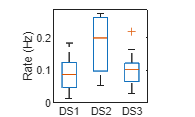

figure
boxplot(DSrate_A, 'Labels',{'DS1', 'DS2', 'DS3'})
axis square
ylabel("Rate (Hz)")


%do stats - repeated measure anova
T = array2table(DSrate_A, 'VariableNames', {'DS1','DS2','DS3'});
rm = fitrm(T, 'DS1-DS3 ~ 1', 'WithinDesign', table([1 2 3]', 'VariableNames', {'Condition'}));
ranovatbl = ranova(rm);
disp(ranovatbl);

                              SumSq      DF     MeanSq        F        pValue      pValueGG    pValueHF     pValueLB
                             ________    __    _________    ______    _________    ________    _________    ________

    (Intercept):Condition    0.057833     2     0.028917    6.1843    0.0073938    0.01222     0.0086294    0.030205
    Error(Condition)          0.10287    22    0.0046758                                                            



rate_posthoc = multcompare(rm, 'Condition', 'ComparisonType', 'bonferroni');

Data A vs B vs C - proportion of DS3s

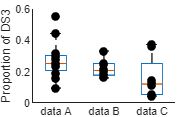

figure
boxplot([DSrelrate_A(:,3); DSrelrate_B(:,3); DSrelrate_C(:,3)], ...
        [ones(12,1); 2*ones(8,1); 3*ones(8,1)], ...
        'Labels', {'data A', 'data B', 'data C'});
hold on
plot(ones(12,1), DSrelrate_A(:,3), "ko", MarkerFaceColor= "k")

plot(ones(8,1)+1, DSrelrate_B(:,3), "ko", MarkerFaceColor= "k")
plot(ones(8,1)+2, DSrelrate_C(:,3), "ko", MarkerFaceColor= "k")
ylim([0 0.6])
xticks(1:3)
xticklabels({"data A", "data B", "data C"})
ylabel("Proportion of DS3")
box off

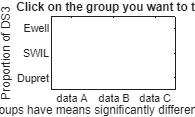


% do stats
n = 3;
x = [DSrelrate_A(:,3)', DSrelrate_B(:,3)', DSrelrate_C(:,3)'];
group = [repmat({'Ewell'},1, 12), ...
    repmat({'SWIL'},1, 8), ...
    repmat({'Dupret'},1, 8), ...
    ];

[p, tbl, stats] = anova1(x, group, "off");

c_ds3 = multcompare(stats, "CriticalValueType","bonferroni");

Compare sink magnitudes (Supplementary Figure 1) - data A & B

meanSinkDS1 = zeros(20,1);
meanSinkDS2 = zeros(20,1);
meanSinkDS3 = zeros(20,2);

for i = 1:12
    
    meanSinkDS1(i) =mean(Cont_A{i}.OML(Cont_A{i}.DStype == 1));
    meanSinkDS2(i) =mean(Cont_A{i}.MML(Cont_A{i}.DStype == 2));
    meanSinkDS3(i,1) =mean(Cont_A{i}.OML(Cont_A{i}.DStype == 3));
    meanSinkDS3(i,2) =mean(Cont_A{i}.OML(Cont_A{i}.DStype == 3));

end

Undefined variable 'Cont_Al'.


for i = 1:8
    meanSinkDS1(i+12) =mean(Cont_B{i}.OML(Cont_B{i}.DStype == 1));
    meanSinkDS2(i+12) =mean(Cont_B{i}.MML(Cont_B{i}.DStype == 2));
    meanSinkDS3(i+12,1) =mean(Cont_B{i}.OML(Cont_B{i}.DStype == 3));
    meanSinkDS3(i+12,2) =mean(Cont_B{i}.MML(Cont_B{i}.DStype == 3));

end


figure
tiledlayout(1,2)
nexttile;
hold on
boxplot([abs(meanSinkDS1); abs(meanSinkDS3(:,1))], [ones(20,1); ones(20,1).*2])
plot(ones(20,1), abs(meanSinkDS1), 'ko', MarkerFaceColor='k' ,MarkerSize=3)
plot(ones(20,1)*2, abs(meanSinkDS3(:,1)), 'ko', MarkerFaceColor='k',MarkerSize=3)
ylim([0 0.15])
xlim([0.5 2.5])
ylabel("Current sink magnitude (oml)")
box off
for i  =1:20
    plot([1 2], [abs(meanSinkDS1(i)) abs(meanSinkDS3(i,1))], 'k-')
end



nexttile;
hold on
boxplot([abs(meanSinkDS2); abs(meanSinkDS3(:,2))], [ones(20,1); ones(20,1).*2])
plot(ones(20,1), abs(meanSinkDS2), 'ko', MarkerFaceColor='k',MarkerSize=3)
plot(ones(20,1).*2, abs(meanSinkDS3(:,2)), 'ko', MarkerFaceColor='k',MarkerSize=3)
ylim([0 0.15])
xlim([0.5 2.5])
ylabel("Current sink magnitude (mml)")
box off
for i  =1:20
    plot([1 2], [abs(meanSinkDS2(i)) abs(meanSinkDS3(i,2))], 'k-')
end